# Texture analysis

This tutorial explains how to compute texture features from 2D en-face maps.

This en-face maps can be extracted from both thickness and reflectance data. 

Tutorial steps:

- Load an OCT volume.

- Create an en-face thickness map.

- Compute texture features (fractal dimension, GLCM, LBP).

If you need help, feel free to reach us at **dromero@mondragon.edu**

close all;clc;clearvars;
addpath(genpath('../src'));

### Load a file

Let's first load an OCT file with segmentation

file = 'data/example_raster.vol';
[header, seg] = read_vol(file, 'get_coordinates');
X = header.X_oct;
Y = header.Y_oct;

### **Compute thickness map**

We now compute the total retinal thickness (TRT)

layers = {'TRT'};
Thickness = compute_thickness(seg, layers, header.scale_z);
TRT = Thickness.TRT;

Our data is highly anisotropic (25 B-scans and 512 A-scans) so it's convenient to resample the thickness map to have homogeneous density.

Here we interpolate the original map into a regular grid of `100 x 100` points covering the region of `[-3, 3] mm` 

[X_reg, Y_reg, TRT_reg] = resample_map(X, Y, TRT, 'regular', 'max_d', 3, 'n_point', 100);

We can visualize the maps as

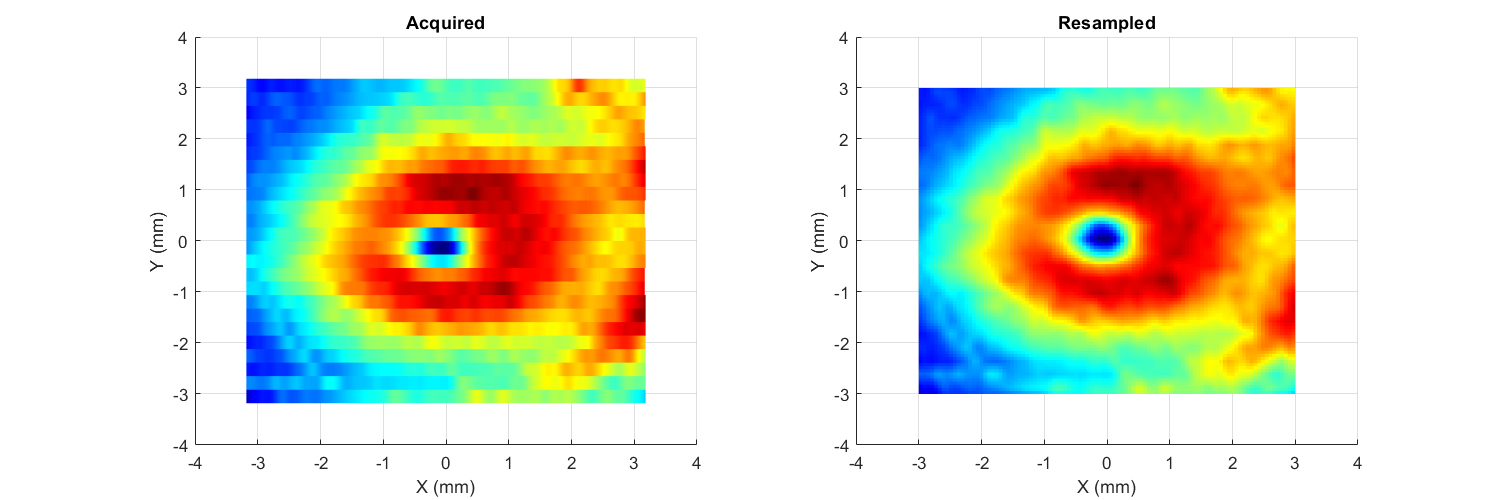

f = figure('Position', [0 0 1200 400]);
subplot(121); 
surf(X, Y, TRT, 'EdgeColor', 'none'); view(0, 90); 
xlabel('X (mm)'); ylabel('Y (mm)'); title({'Acquired'});
axis(4 * [-1 1 -1 1]);

subplot(122);
surf(X_reg, Y_reg, TRT_reg, 'EdgeColor', 'none');view(0,90)
xlabel('X (mm)'); ylabel('Y (mm)'); title({'Resampled'});
axis(4 * [-1 1 -1 1]);

colormap(jet);

## **Feature extraction**

A 2D thickness map can be considered as a surface and we can measure its properties by means of texture analysis.

Here we describe three of the many existing approaches for texture analysis.

### **Fractal analysis**

Fractal dimension (FD) is a measure of the roughness of the surface.

To be computed we first need to discretize our surface into fixed levels.

TRT_int = map2uint8(TRT_reg);

We can now compute FD

fd = fractal_dimension(TRT_int)

fd = 2.0962

To illustrate how FD is related to roughness let's measure it again adding noise to the surface.

We can now let `RETIMAT` discretize the surface (it will show a warning though)

fd_noise = fractal_dimension(TRT_reg + randn(size(TRT_reg)))

fd_noise = 2.1105

We see how FD increases as the surface is more noisy.

### **Gray-level co-ocurrence matrix (GLCM)**

In this approach the first goal is to compute a matrix that relates the intensities of neighbouring pixels.

We can compute the GLCM matrix with the

offset = [1 0];  % compare each pixel with its vertically adjacent 
n_level = 100;
thick_lims = minmax(TRT_reg(:)');

GLCM = graycomatrix(TRT_reg, 'GrayLimits', thick_lims, 'NumLevels', n_level, ...
                'Offset', offset, 'Symmetric', true);

Note that we had to define the offset describint how to relate adjacent pixels and the number of levels to discretize the map (100 in this case).

We can visualize the matrix

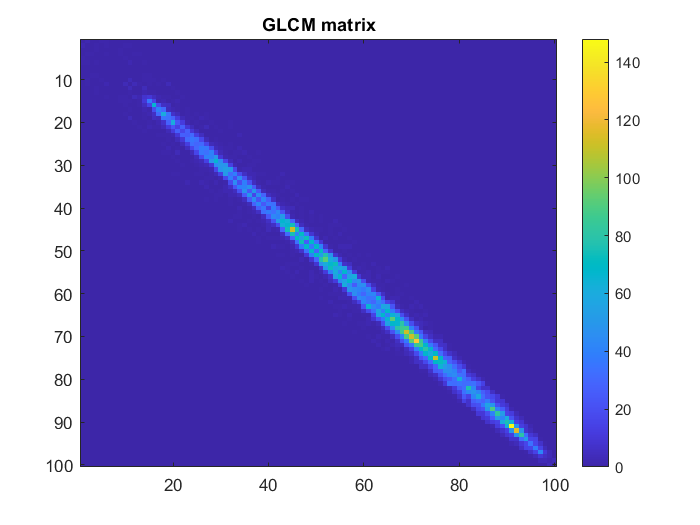

f = figure();
imagesc(GLCM);
colorbar;
title('GLCM matrix');

This matrix can be conceived as a 2D histogram describing which combinations of pixel values were more likely.

From this matrix we can extract numeric features by:

Features_glcm = GLCM_features(GLCM)

Features_glcm = struct with fields:
                   autocorrelation: 3.9723e+03
                cluster_prominence: 6.8074e+06
                     cluster_shade: -1.9575e+04
                          contrast: 3.7062
                       correlation: 0.9958
                      dif_variance: 1.7718
                       dif_entropy: 2.1229
                     dissimilarity: 1.3908
                            energy: 0.0024
                           entropy: 9.0721
                              IMC1: -0.5633
                              IMC2: 0.9996
                inverse_difference: 0.5362
           inverse_difference_norm: 0.9864
         inverse_difference_moment: 0.4868
    inverse_difference_moment_norm: 0.9996
                    joint_variance: 1.5311e+07
                          max_prob: 0.0075
                    sum_of_squares: 440.5934
                       sum_average: 118.8874
                       sum_entropy: 7.2972


Most of these features are considered as Haralick features. See the references listed in the docstrings of `GLCM_features()` for more details into their computation.

An important parameter choice is the `offset`. The value set before `([1,0])` means that we are building a GLCM matrix by comparing vertically adjacent pixels.

A more complete approach is to build 4 matrices for adjacent pixels along vertical, horizontal and both diagonals axes.

Then, we can compute the features for each direction and average them

offset = [1 0; 0 1; -1 -1; -1 1]; % 4 directions (vert, horiz + 2 diagonals)
offset_name = {'vertical', 'horizontal', 'diag_up', 'diag_down'};

T = table;
for i=1:4
    GLCM = graycomatrix(TRT_reg, 'GrayLimits', thick_lims, 'NumLevels', n_level, ...
                                 'Offset', offset(i,:), 'Symmetric', true);
    T = [T; struct2table(GLCM_features(GLCM))];
end

Features_glcm_mean = table2struct(varfun(@mean, T))

Features_glcm_mean = struct with fields:
                   mean_autocorrelation: 3.9736e+03
                mean_cluster_prominence: 6.7182e+06
                     mean_cluster_shade: -1.9000e+04
                          mean_contrast: 4.8241
                       mean_correlation: 0.9945
                      mean_dif_variance: 2.2596
                       mean_dif_entropy: 2.2429
                     mean_dissimilarity: 1.5779
                            mean_energy: 0.0022
                           mean_entropy: 9.2218
                              mean_IMC1: -0.5389
                              mean_IMC2: 0.9994
                mean_inverse_difference: 0.5092
           mean_inverse_difference_norm: 0.9847
         mean_inverse_difference_moment: 0.4518
    mean_inverse_difference_moment_norm: 0.9995
                    mean_joint_variance: 1.5321e+07
                          mean_max_prob: 0.0059
                    mean_sum_of_squares: 437.6915
                       mean

### Linear binary patterns (LBP)

Like `GLCM`, the `LBP` approach is also based on exploring the relationship between adjacent pixel.

In this case each pixel is compared to its neighbours by a circular structuring element.

After applying the operation to every pixel a histogram is built.

Statistical descriptors describint the histogram are the `LBP` features.

We can extract them by:

n_neighbor = 6;
Features_lbp = LBP_features(map2uint8(TRT_reg), n_neighbor)

Features_lbp = struct with fields:
        mean: 0.1035
      median: 0.0397
         std: 0.1421
         iqr: 0.1361
       range: 0.4871
    skewness: 1.7388
    kurtosis: 4.9393
     entropy: 4.0006
